# **=================================================**   **Gaussian Beam Simulation Using FFT Propagation**

# **lambda = 3 mm and w0 = 10 mm**

# **=================================================**

clear; close all; clc;

## ====== PARAMETERS ========================================

lambda = 3e-3;          % Wavelength (m)
w0 = 10e-3;             % Beam waist (m)
k  = 2*pi/lambda;        % Wavenumber
z0 = pi*w0^2/lambda;    % Rayleigh range
A0 = 1;

## ====== SAMPLING GRID ======================================

L  = 40*w0;     
dx_min = sqrt(2)*pi/k ;
dx = dx_min + 0.1e-3 ;
x = -L/2:dx:L/2;
y = x;
[X,Y] = meshgrid(x,y);
N  = length(x);

## ====== SPATIAL FREQUENCY GRID =============================

dk = 2*pi/dx;
kx =linspace(-dk/2,dk/2,N);
ky = kx;
[KX,KY] = meshgrid(kx,ky);
KZ_squared = k^2 - KX.^2 - KY.^2;
KZ = sqrt(max(0,KZ_squared));

## ====== INITIAL GAUSSIAN FIELD ===============================

U0 = A0 * exp(-(X.^2 + Y.^2)/w0^2);

## ====== PART 1 ==============================================

### **PROPAGATION AT :0, 0.5 z0,z0**

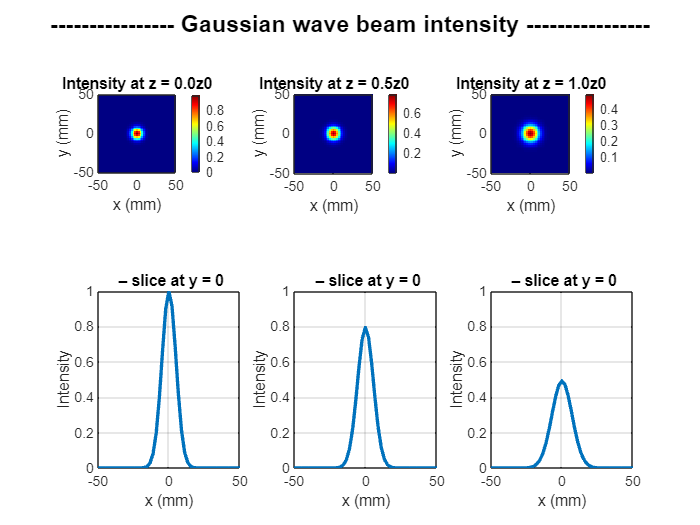

z_list = [0, 0.5*z0, z0];

for z = z_list
    Uz = propagate_fft(U0, z, KZ);
    plot_intensity(Uz, x, z/z0, sprintf('Intensity at z = %.1fz0', z/z0));
end

## ====== PART 2 – PARABOLIC MIRROR (f = -4z0) ===================

### **PROPAGATION** TO: 3z0, 4z0, 5z0 → REFLECT TO→ z0, 4z0, 6z0

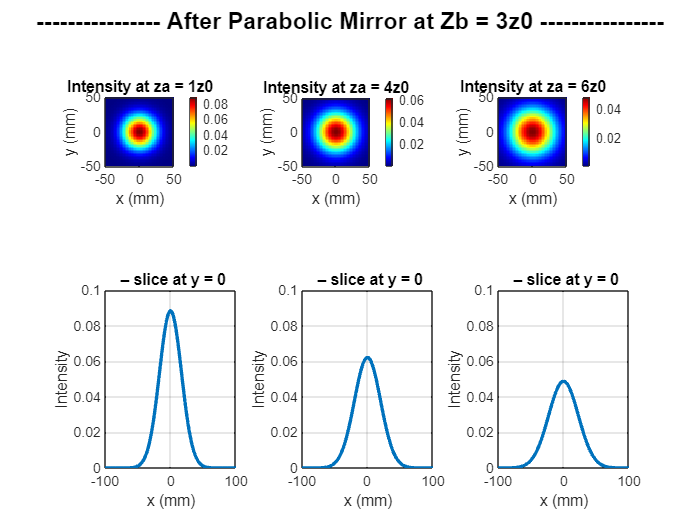

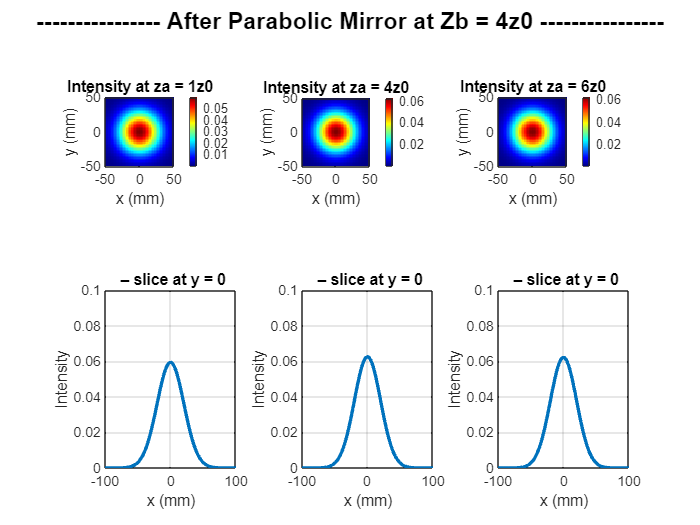

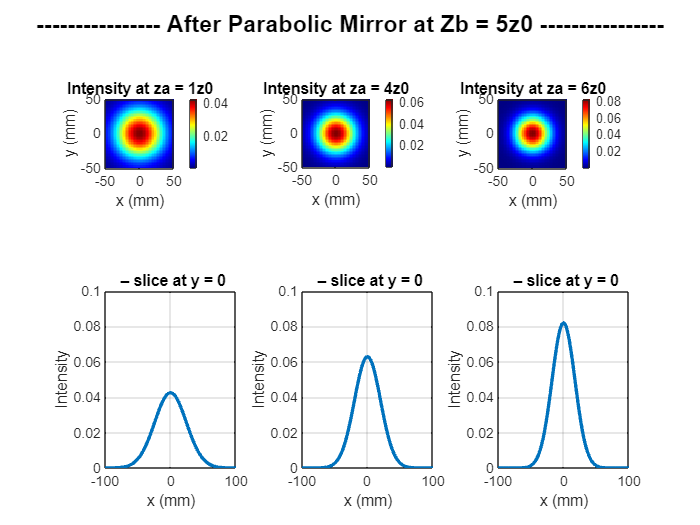

f = -4*z0;
M = exp(-1i * k * (X.^2 + Y.^2) / (2*f));

z_before = [3*z0, 4*z0, 5*z0];
z_after_list = [z0, 4*z0, 6*z0];

for zb = z_before
    U_before = propagate_fft(U0, zb, KZ);
    U_after = M .* U_before;
    
    for za = z_after_list
        Uout = propagate_fft(U_after, za, KZ);
        plot_intensity_mirror(Uout, x,zb/z0,za/z0, ...
            sprintf('Intensity at za = %.0fz0', za/z0));
    end
end

## ====== FUNCTION DEFINITIONS ================================

function Uz = propagate_fft(U, z, KZ)
    H = exp(-1i * KZ * z);
    Uz = ifft2(ifftshift(fftshift(fft2(U)) .* H));
end

function plot_intensity(U, x,index, title_str)
I = abs(U).^2;

if index == 0
    position = 1;
    figure;
    sgtitle('---------------- Gaussian wave beam intensity ----------------','FontWeight','bold');
elseif index == 0.5
    position = 2;
elseif index == 1
    position = 3;
end
subplot(2,3,position);
x_mm = x*1e3;
imagesc(x_mm, x_mm, I);
axis xy;axis equal;colormap jet; colorbar;shading interp;
xlabel('x (mm)');ylabel('y (mm)');
title(title_str);
xlim([-50,50]);
ylim([-50,50]);

% Slice at y=0
idx = round(length(x)/2);
I_x = I(idx,:);
subplot(2,3,position+3);
plot(x_mm, I_x, 'LineWidth', 2);
xlabel('x (mm)');ylabel('Intensity');
title(' – slice at y = 0');
ylim([0,1]);
xlim([-50,50]);
grid on;
end

function plot_intensity_mirror(U, x,index1,index2, title_str)
I = abs(U).^2;

if index1 == 3 && index2==1
    figure;
    sgtitle('---------------- After Parabolic Mirror at Zb = 3z0 ----------------','FontWeight','bold');
elseif index1 == 4 && index2==1
    figure;
    sgtitle('---------------- After Parabolic Mirror at Zb = 4z0 ----------------','FontWeight','bold');
elseif index1 == 5 && index2==1
    figure;
    sgtitle('---------------- After Parabolic Mirror at Zb = 5z0 ----------------','FontWeight','bold');
end
if index2 == 1
    position = 1;
elseif index2 == 4
    position = 2;
elseif index2 == 6
    position = 3;
end
subplot(2,3,position);
x_mm = x*1e3;
imagesc(x_mm, x_mm, I);
axis xy;axis equal;colormap jet; colorbar;shading interp;
xlabel('x (mm)');ylabel('y (mm)');
title(title_str);
xlim([-50,50]);
ylim([-50,50]);

% Slice at y=0
idx = round(length(x)/2);
I_x = I(idx,:);
subplot(2,3,position+3);
plot(x_mm, I_x, 'LineWidth', 2);
xlabel('x (mm)');ylabel('Intensity');
title(' – slice at y = 0');
ylim([0,0.1]);     % auto-scale to max intensity
xlim([-100,100]);
grid on;
end